# Identifying a 2D SSM for an oscillator chain

This is an example of how to reconstruct a slow 2D SSM of a mechanical system using synthetic measurements of the full state space. In this example, we consider a damped oscillator chain with an additional nonlinear spring attached to the leftmost mass. The measurements for this example are transients occurring from exact initial conditions on the slow 2D SSM.

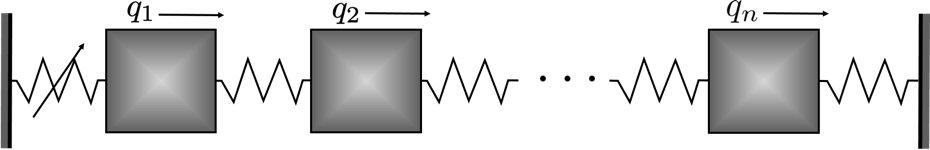

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{y}} = \mathbf{A}\mathbf{y} + \mathbf{G}(\mathbf{y}) = \mathbf{F}(\mathbf{y})$$


with

$\mathbf{y}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{y})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{y})\end{array}\right]$.

n         = 5;      % number of masses
mass      = 1;
mass1     = 1.5;
stiffness = 1;
dampingM   = 0.002;
dampingK   = 0.005;

vMass = ones(1,n);%fliplr(linspace(0.5,1,n)); %
M = mass*diag(vMass); M(1,1) = mass1;
K = stiffness*(2*eye(n) - diag(ones(1,n-1),-1) - diag(ones(1,n-1),1));
K(end,end) = 1;
C = dampingM*M + dampingK*K;

% nonlinearities: f1 = 0.33*q1dot^2 + 3*q1^3 + 0.7*q1^2*q1dot + 0.5*q1dot^3
F2 = sptensor(zeros(n, 2*n, 2*n)); F3 = sptensor(zeros(n, 2*n, 2*n, 2*n));
F2(1,n+1,n+1) = 0.33;    % q1dot^2
F3(1,1,1,1) = 3;         % q1^3
F3(1,1,1,n+1) = 0.7;     % q1^2*q1dot 
F3(1,n+1,n+1,n+1) = 0.5; % q1dot^3
fnl = {F2*mass1, F3*mass1};
[F, lambda, E] = functionFromTensors(M, C, K, fnl);

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation.

nTraj = 2;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);

We now set the initial conditions for the trajectories, which are picked exactly on the slowest 2D SSM of the systems, computed using SSMTool.

ICRadius = 0.6;
IC = getSSMIC(M, C, K, fnl, nTraj, ICRadius, 2, 1);

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 4.245669e-03
modal damping ratio for 2 mode is 3.236388e-03
modal damping ratio for 3 mode is 3.848172e-03
modal damping ratio for 4 mode is 4.639624e-03
modal damping ratio for 5 mode is 5.267721e-03

 The first 10 eigenvalues are given as 
   -0.0011996 +    0.28254i
   -0.0011996 -    0.28254i
   -0.0025406 +      0.785i
   -0.0025406 -      0.785i
   -0.0046493 +     1.2082i
   -0.0046493 -     1.2082i
   -0.0074555 +     1.6069i
   -0.0074555 -     1.6069i
   -0.0099883 +     1.8961i
   -0.0099883 -     1.8961i

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 8
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     1     2
     2 

% Perturbed initial conditions
% ICRadius = 0.55;
% IC = getSSMIC(M, C, K, fnl, nTraj, ICRadius, 2, 1);
% rng('default'); var = 0.01;
% IC = IC + var*randn(2*n,nTraj);

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the full state space, so the `observable` function is the identity.

observable = @(x) x;
slowTime = 2*pi/abs(lambda(1));
nPeriods = 140; 
nDataPerPeriod = 50;
endTime = nPeriods * slowTime;
nSamp = nDataPerPeriod * nPeriods + 1;
dt = endTime/(nSamp-1);
tic
yData = integrateTrajectories(F, endTime, IC, nSamp, observable);

simulating trajectory 1 of 2...
simulating trajectory 2 of 2...


toc

Elapsed time is 1.904291 seconds.


## Plot generated trajectory data

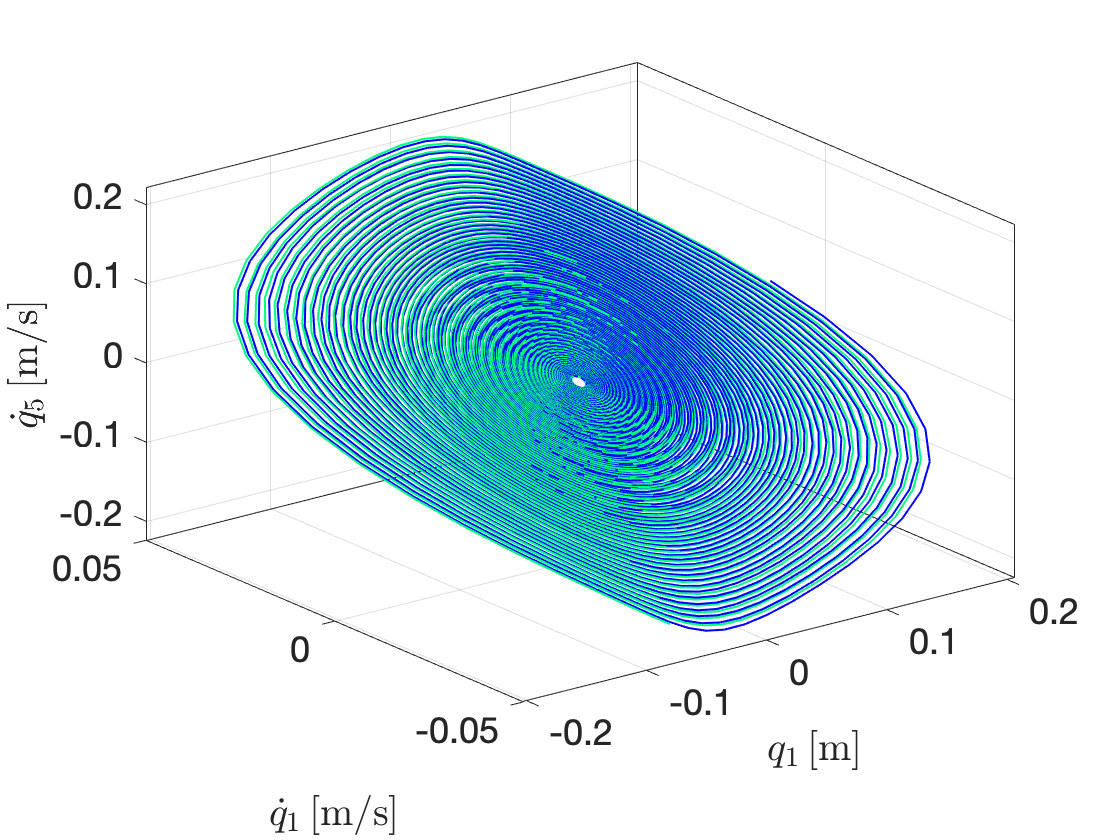

customFigure(); colororder(winter(nTraj));
for iTraj = 1:size(yData,1)
    plot3(yData{iTraj,2}(1,:), yData{iTraj,2}(n+1,:), yData{iTraj,2}(2*n,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlabel('$q_1 \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_1 \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$\dot{q}_{' num2str(n) '} \, [$m/s$]$'],'Interpreter','latex'); 
view(3)

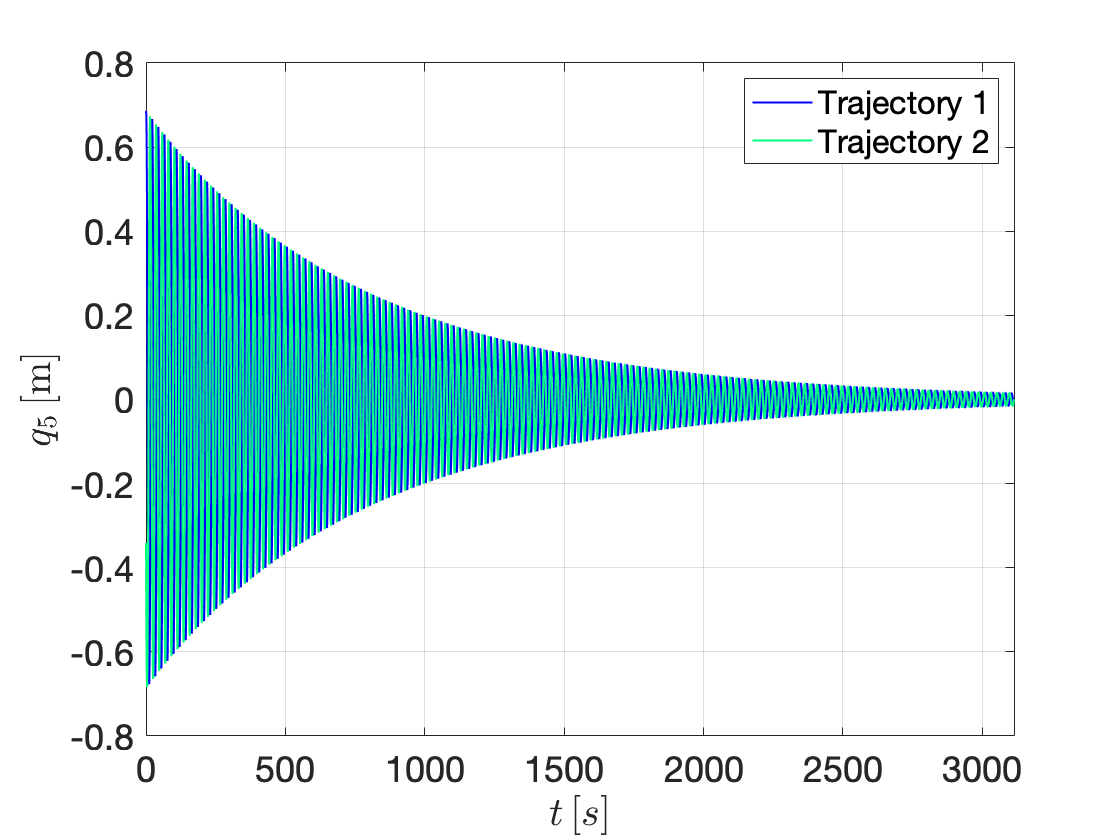



customFigure(); colororder(winter(nTraj));
for iTraj = 1:size(yData,1)
    plot(yData{iTraj,1}, yData{iTraj,2}(n,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlim([0 endTime])
xlabel('$t \, [s]$','Interpreter','latex'); 
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 
legend('location','NE')

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. 

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimizing a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top 
y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab routine `fmincon` in `IMGeometry`.

SSMOrder = 3; SSMDim = 2;
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yData(indTrain,:), SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.442668e-07    8.882e-16    2.591e-05
    1       2    2.432199e-07    7.717e-10    2.546e-05    3.245e-05
    2       3    2.382472e-07    1.875e-08    2.324e-05    1.602e-04
    3       4    2.192137e-07    4.113e-07    1.290e-05    7.517e-04
    4       5    2.017444e-07    1.993e-06    1.819e-05    1.659e-03
    5       6    2.012335e-07    1.043e-09    1.829e-05    4.655e-05
    6       7    1.986301e-07    6.291e-09    1.802e-05    1.493e-04
    7       8    1.867949e-07    1.354e-07    1.650e-05    7.081e-04
    8       9    1.518798e-07    2.656e-06    1.000e-05    3.129e-03
    9      10    1.437206e-07    1.436e-06    1.547e-05    2.280e-03
   10      11    1.429833e-07    8.175e-09    1.256e-05    1.557e-04
   11      12    1.389882e-07    4.775e-08    1.210e-05    3.715e-04
   12      13    1.228946e-07    5.923e-07    9

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace and plot the SSM. 

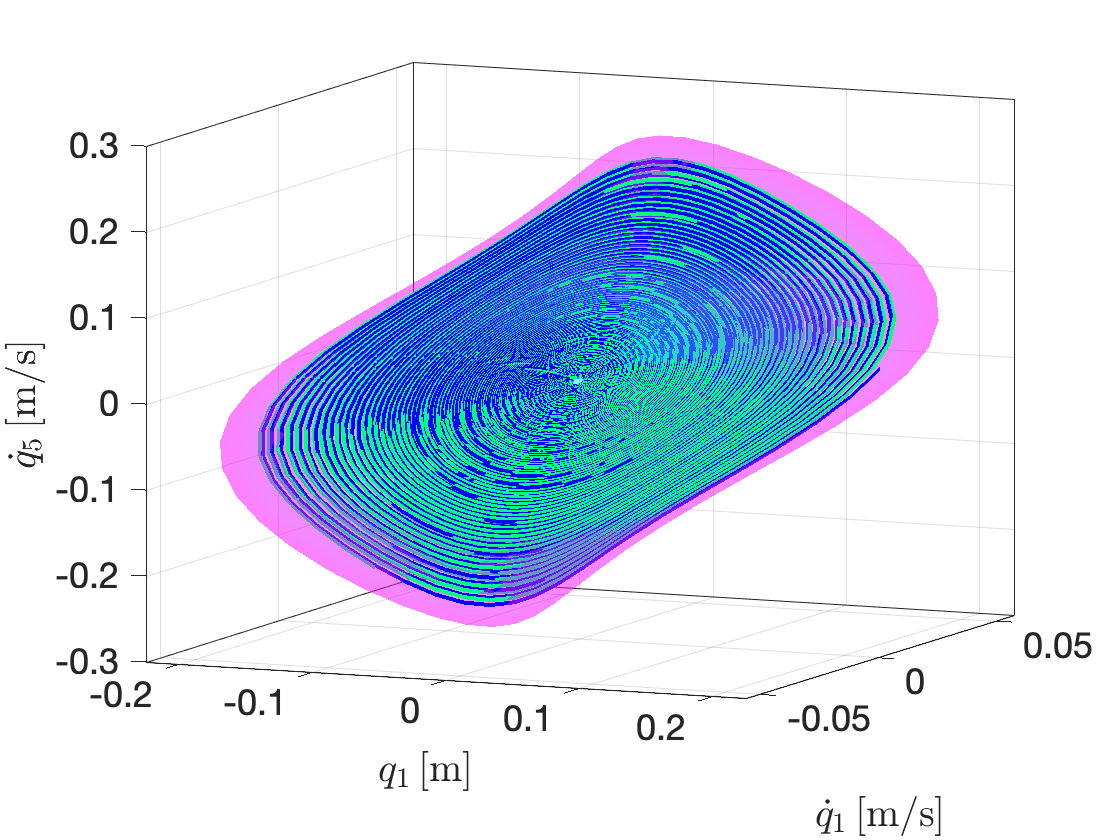

etaData = projectTrajectories(IMInfo, yData);
coordPlot = [1 n+1 2*n];
plotSSMandTrajectories(IMInfo, coordPlot, yData,etaData,'Margin',10,'ColorTraj', winter(nTraj));
xlabel('$q_1 \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_1 \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$\dot{q}_{' num2str(n) '} \, [$m/s$]$'],'Interpreter','latex'); legend('off')
view(24,10)

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and  $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics in normal form, so that the map $N$ will fulfill


$$\dot{z} = N(z) = Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) = \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change. The polar normal form of the dynamics for this 2D SSM case has the form

$\dot{\rho} = c(\rho)\rho$ ,

$\dot{\theta} =  \omega(\rho)$ ,

which is identified from data using the function `IMDynamicsFlow` under the 'normalform' style.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      1.85825e-06                       3.8e-05
     1           5      8.55689e-07            820       2.73e-05  
     2           6      3.91187e-07              1        4.9e-05  
     3           7      1.77575e-08              1       5.85e-06  
     4           8      4.10589e-09              1       1.17e-06  
     5           9      2.88453e-09              1       3.32e-07  
     6          10       2.7656e-09              1       2.06e-07  
     7          11      2.69076e-09              1       3.37e-07  
     8          12      2.68618e-09              1       3.27e-07  
     9          13      2.67328e-09              1       2.28e-08  
    10          14      2.67271e-09              1       1.77e-08  
    11          15

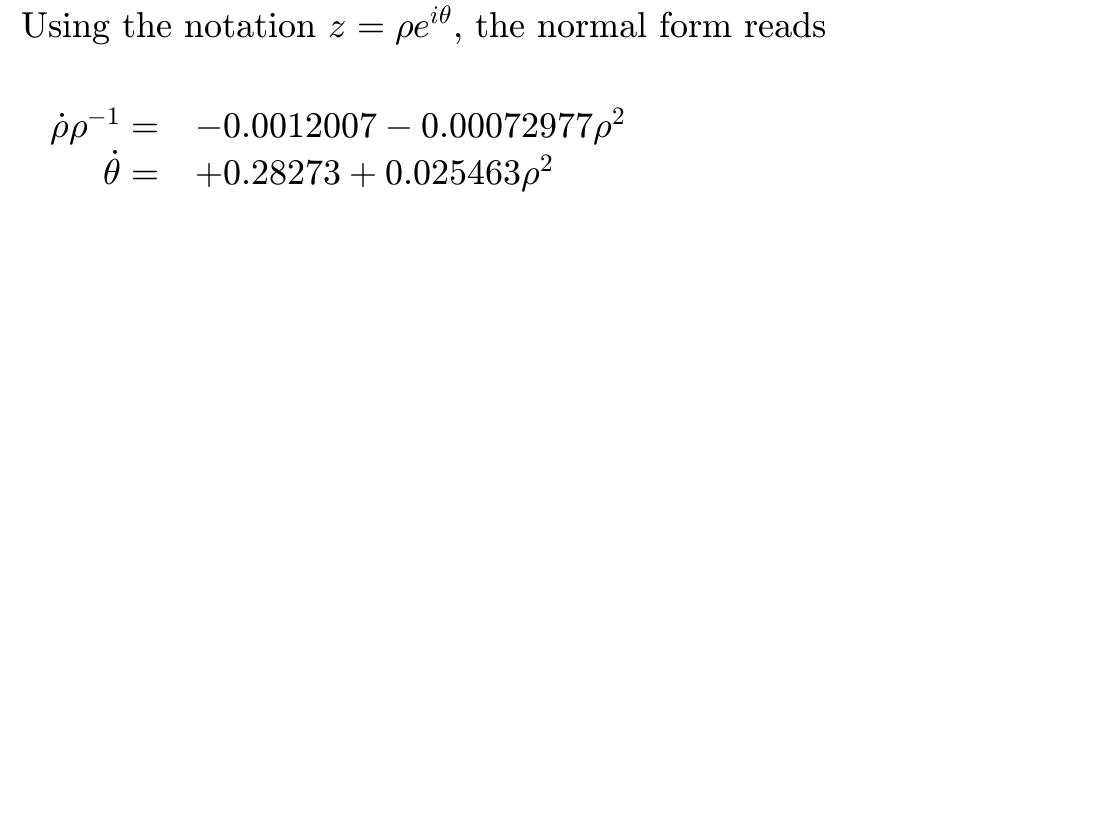

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaData(indTrain,:), 'R_PolyOrd', ROMOrder, 'style', 'normalform');

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and iterate our reduced order evolution rule to predict the development of the trajectory.

[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yData);

## Evaluation of reduced dynamics

The error RRMSE is computed as the average distance of the predicted trajectory to the measured one in the full state space. We also plot the testing trajectory.

% Compute errors
normedTrajDist = computeTrajectoryErrors(yRec, yData);
RRMSE = mean(normedTrajDist(indTest))

RRMSE =     0.0080441


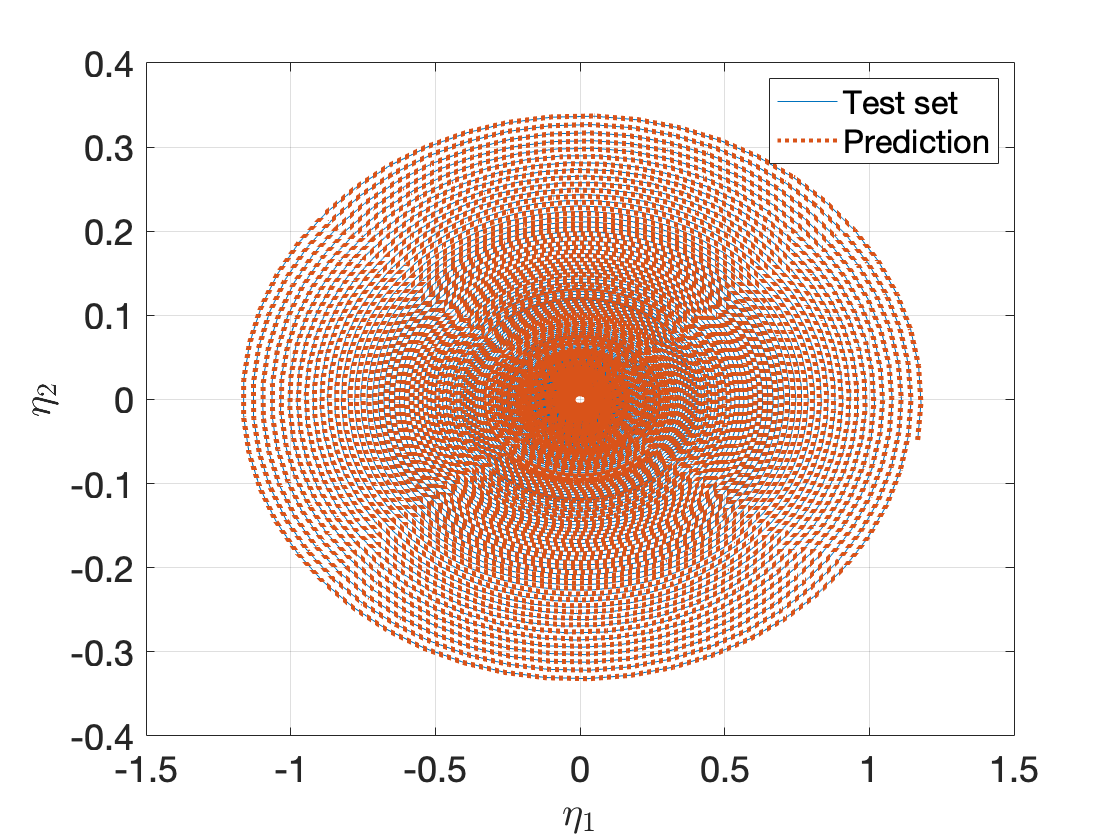


% Plot trajectories
plotReducedCoordinates(etaData(indTest,:), etaRec(indTest,:))
legend({'Test set', 'Prediction'})

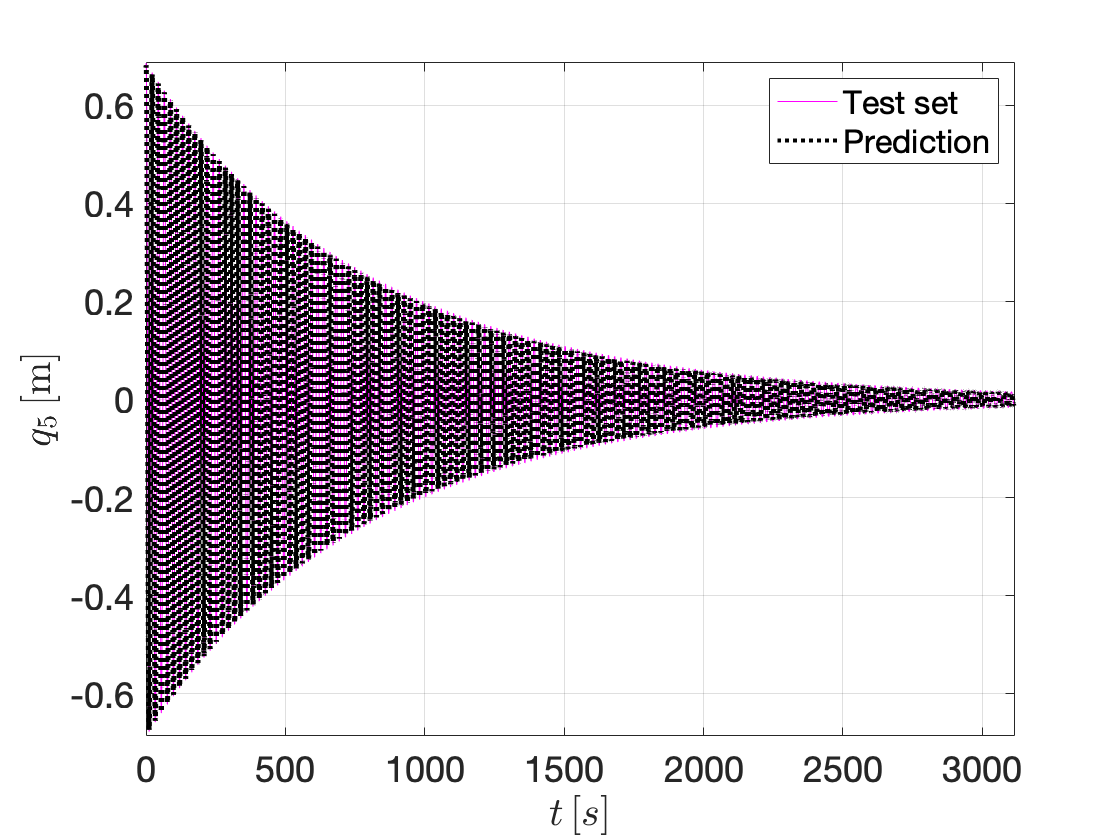

plotTrajectories(yData(indTest,:), yRec(indTest,:), 'm', n, {'Test set', 'Prediction'})
xlabel('$t \, [s]$','Interpreter','latex'); 
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 


% Check eigenvalues
reconstructedEigenvalues = RDInfo.eigenvaluesLinPartFlow;
[lambda(1) reconstructedEigenvalues(1)]

ans =    -0.0011996 +    0.28254i   -0.0012007 +    0.28273i


## Backbone curves and frequency responses

We can now study the reduced order model. We extract backbones curves and forced response curves (FRCs). For the latter, our 

$$\dot{z} =N(z) + f_{red} e^{i\Omega t}$,

where $$\Omega$ is the forcing frequency and $$f_{red}$ is the forcing amplitude. For FRC extraction, we both use the analytical solution, that computes fixed points of the polar normal form with a closed form solution, and numerical continuation of periodic orbits, via the continuation core coco.

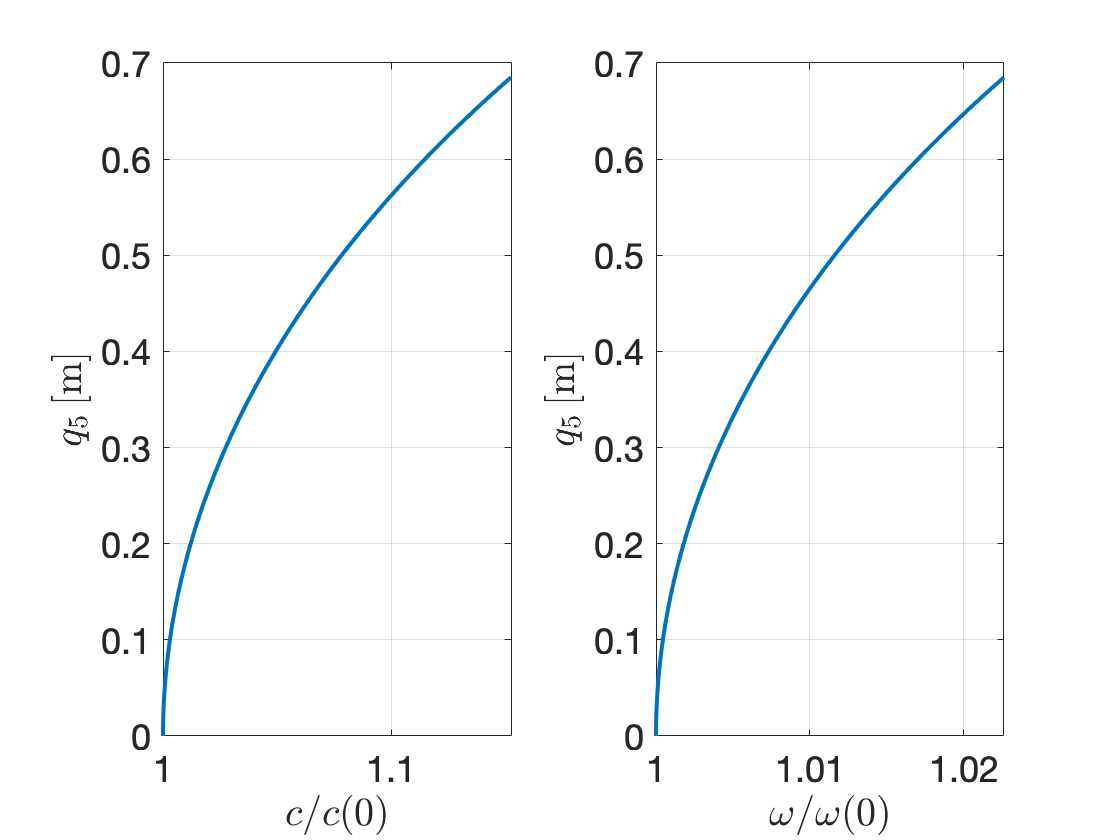

% Define the physical amplitude metric
amplitudeFunction = @(x) x(n,:); maxRho = max(abs(zRec{1,2}(1,:)));

% Compute backbone curves in the training range of data
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction,maxRho, 'norm');
subplot(121);
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 
subplot(122);
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 


% Compute frequency response curves
omegaSpan = [0.95 1.05]*abs(reconstructedEigenvalues(1)); 
amplitudeCal = [0.0732 0.177 0.331 0.5 0.75]; forcingSpan = zeros(1,length(amplitudeCal));

amplitudeCal =        0.0732        0.177        0.331          0.5         0.75


for iCal = 1:length(amplitudeCal)
   [~,pos] = min(abs(BBCInfo.amplitude-amplitudeCal(iCal)));
   forcingSpan(iCal) = -BBCInfo.amplitudeNormalForm(pos)*BBCInfo.damping(pos);
end
[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


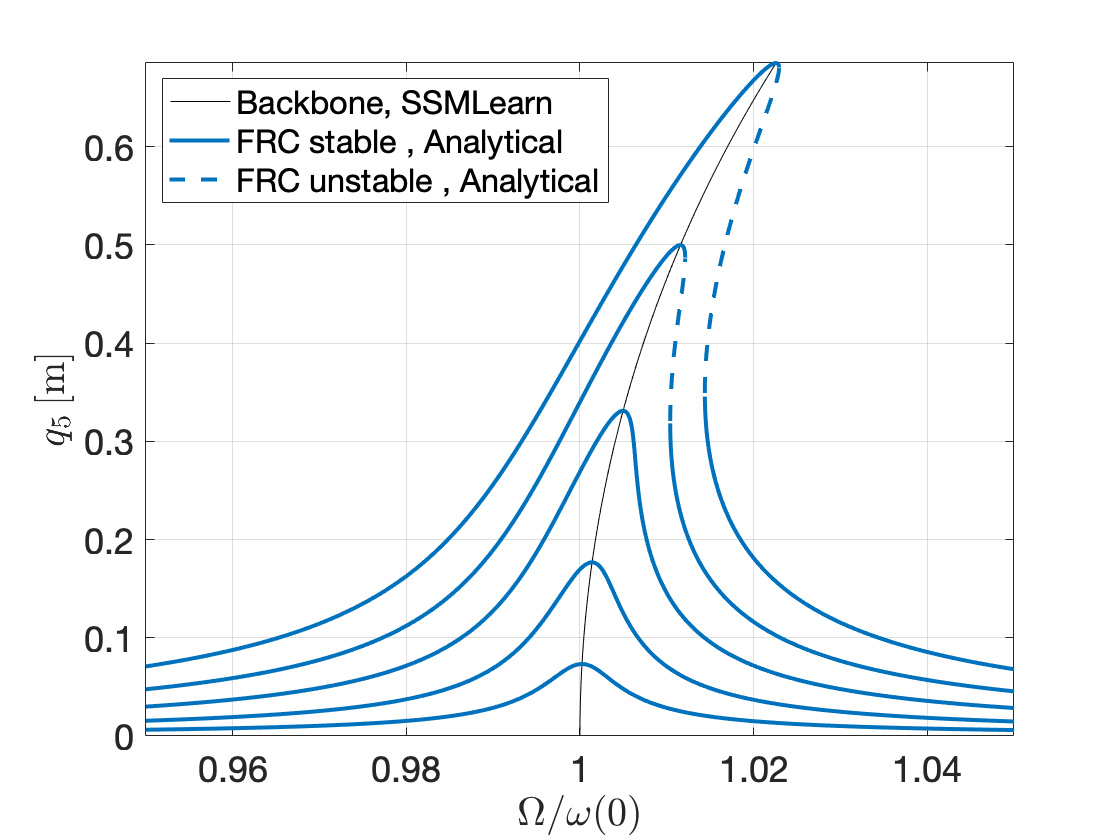

FRCData = analyticalFRC(IMInfoF,RDInfoF,forcingSpan,amplitudeFunction);
%FRCDataCOCO = continuationFRCpo(IMInfoF,RDInfoF,forcingSpan,omegaSpan,amplitudeFunction);

freqNorm = BBCInfo.frequency(1);
% Plot backbone curves and FRCs
customFigure(); colors = colororder;
plot(BBCInfo.frequency/freqNorm, BBCInfo.amplitude,'k','DisplayName','Backbone, SSMLearn')
plotFRC(FRCData, colors(1,:), ', Analytical','freqscale',freqNorm)
%plotFRC(FRCDataCOCO, colors(2,:), ', Numerical','freqscale',freqNorm)
xlim(omegaSpan/freqNorm)
ylim([0 max(BBCInfo.amplitude)])
xlabel('$\Omega/\omega(0)$','Interpreter','latex'); 
ylabel('$q_5 \, [$m$]$','Interpreter','latex'); 
legend('location','NW')